# Opcion A

# Exercici 1

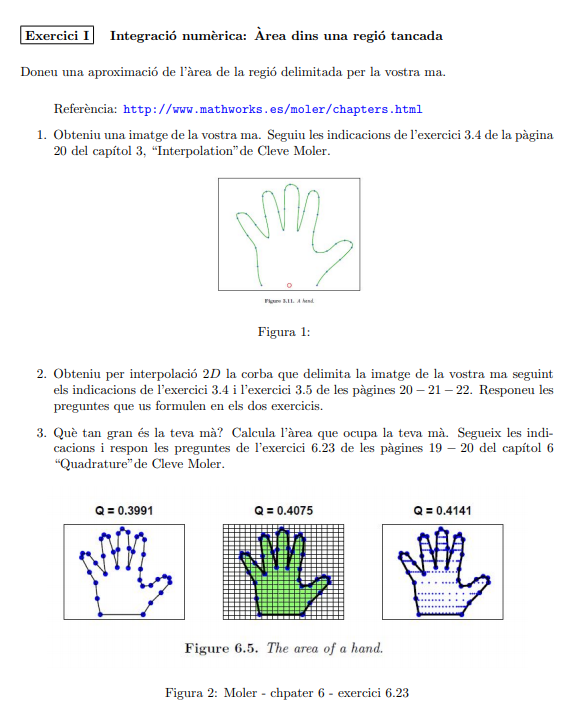

**Exercici 1.2**

clear
figure('position',get(0,'screensize'))
axes('position',[0 0 1 1])
%[x,y] = ginput;
load myhand.mat

# Splinetx

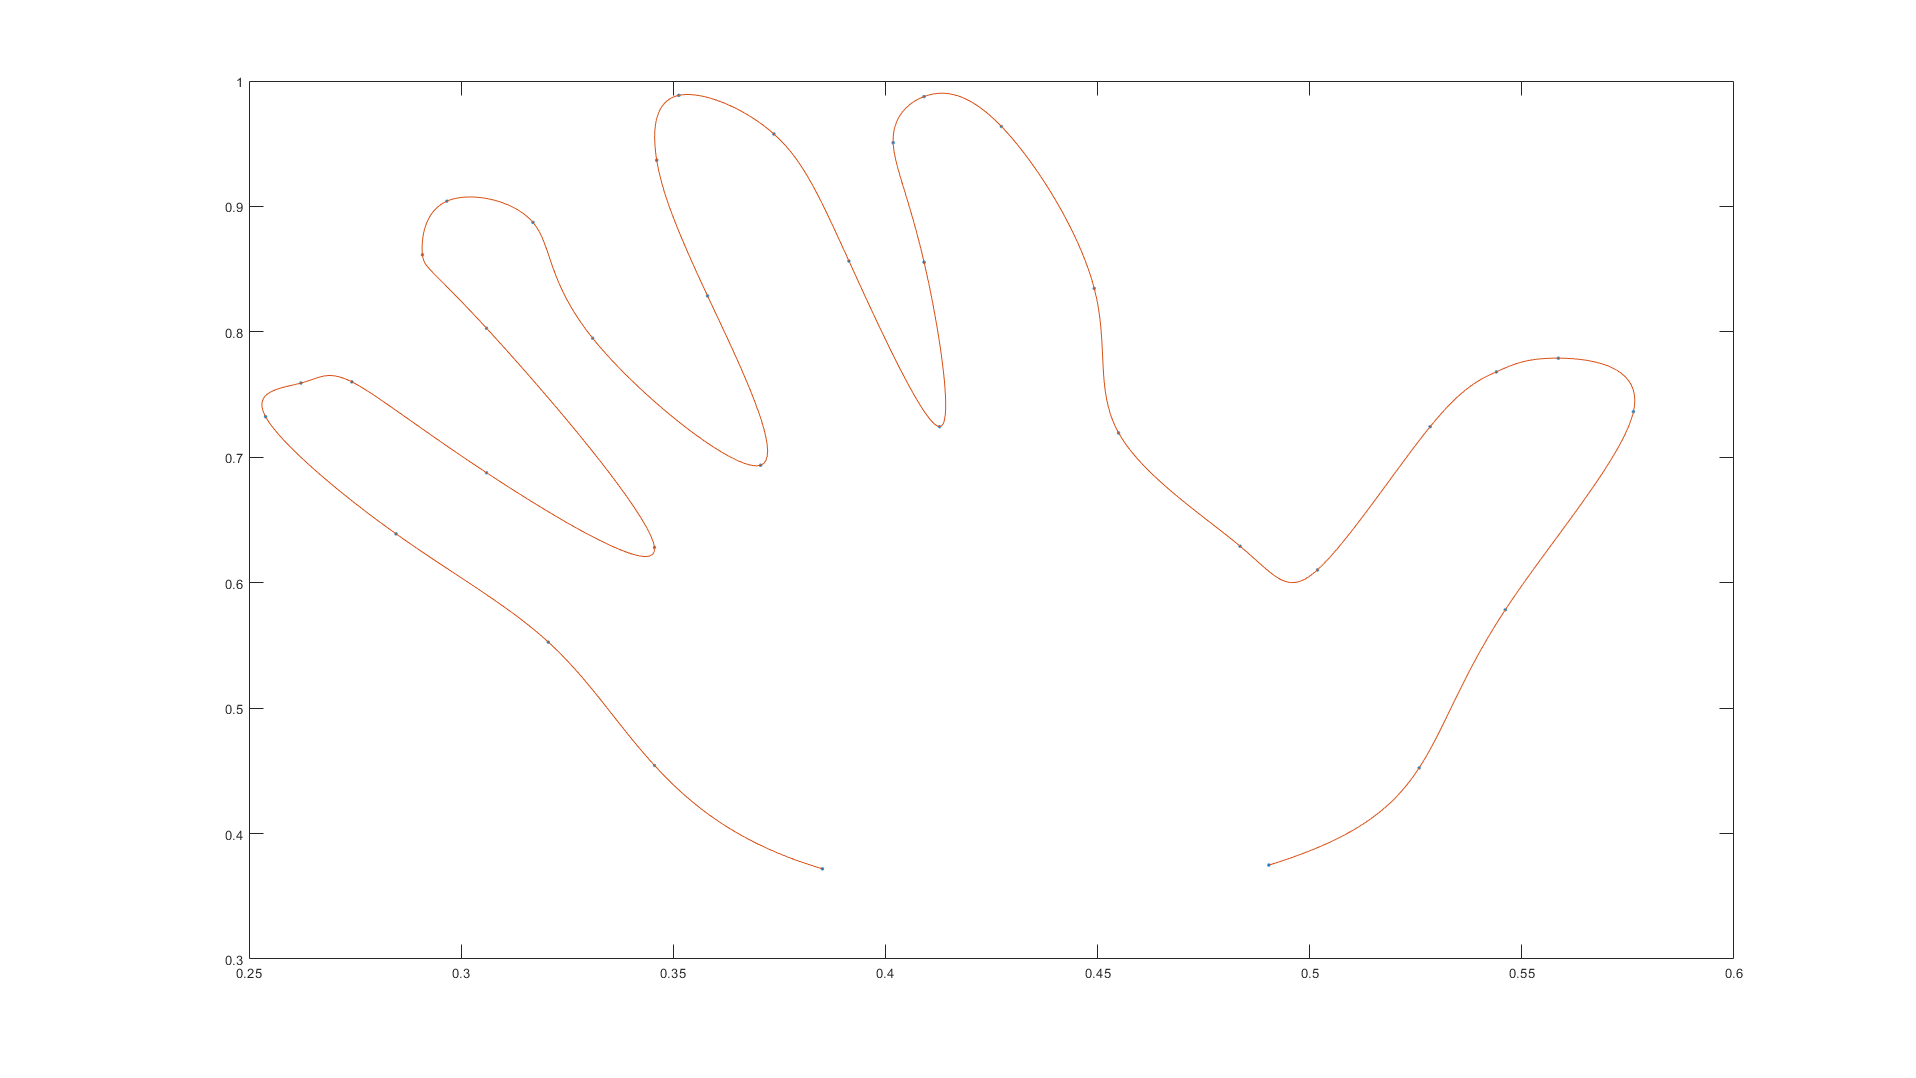

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = splinetx(s,x,t);
v = splinetx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

# pchiptx

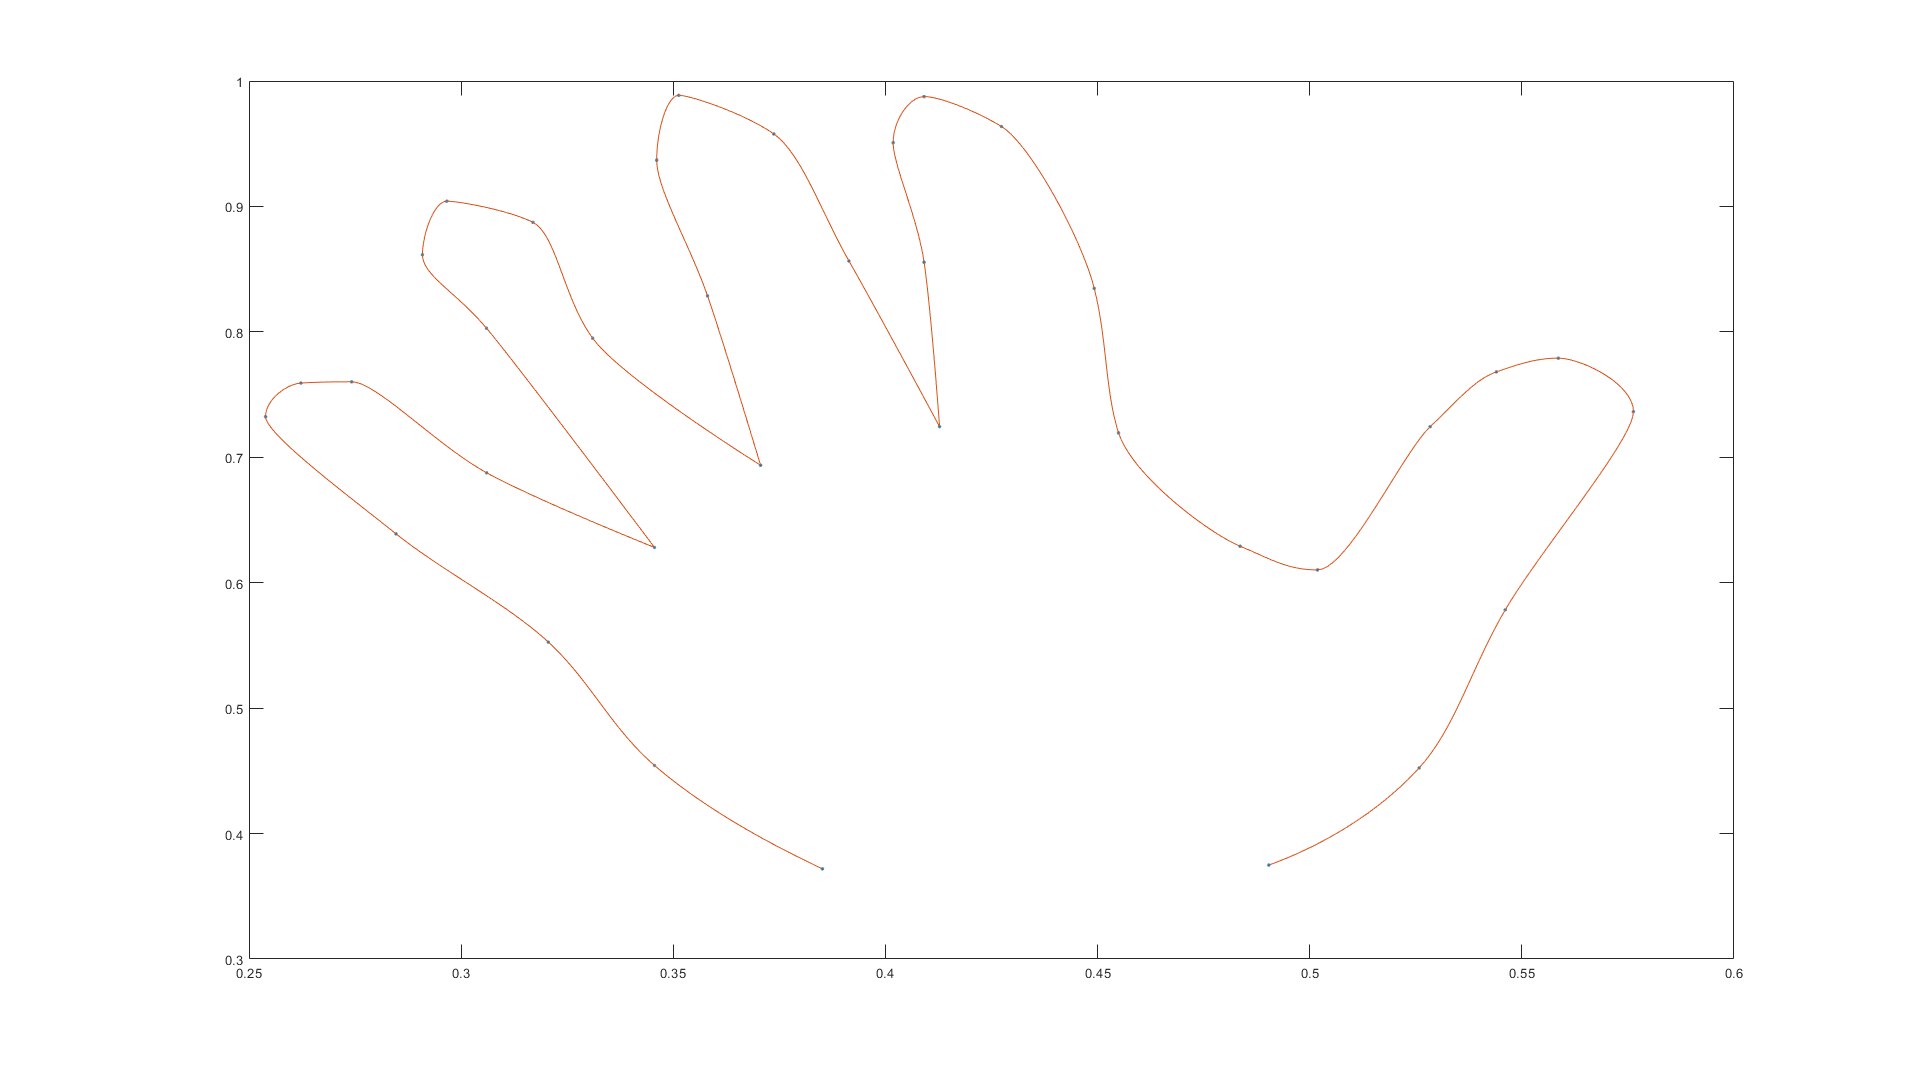

n = length(x);
s = (1:n)';
t = (1:.05:n)';
u = pchiptx(s,x,t);
v = pchiptx(s,y,t);
clf reset
plot(x,y,'.',u,v,'-');

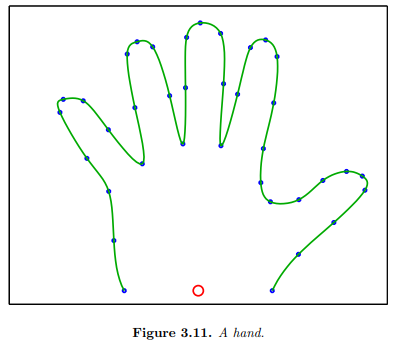

Mas o menos los plots de las manos son parecidas. Aun así prefiero la interpolacion con splinetx ya que hace mejor la forma curvada de la punta de los dedos. Creo que la figura 3.11 se ha hecho con splinetx.

x0 = 0;
y0 =0;
x = x -x0;
y = y - y0;

y =     0.3719
    0.4543
    0.5526
    0.6390
    0.7324
    0.7592
    0.7602
    0.6877
    0.6281
    0.8029


theta = atan2(y,x);

theta =     0.7679
    0.9205
    1.0451
    1.1518
    1.2371
    1.2382
    1.2246
    1.1521
    1.0678
    1.2067


r = sqrt(x.^2 + y.^2);

r =     0.5354
    0.5708
    0.6389
    0.6996
    0.7751
    0.8032
    0.8081
    0.7527
    0.7169
    0.8592


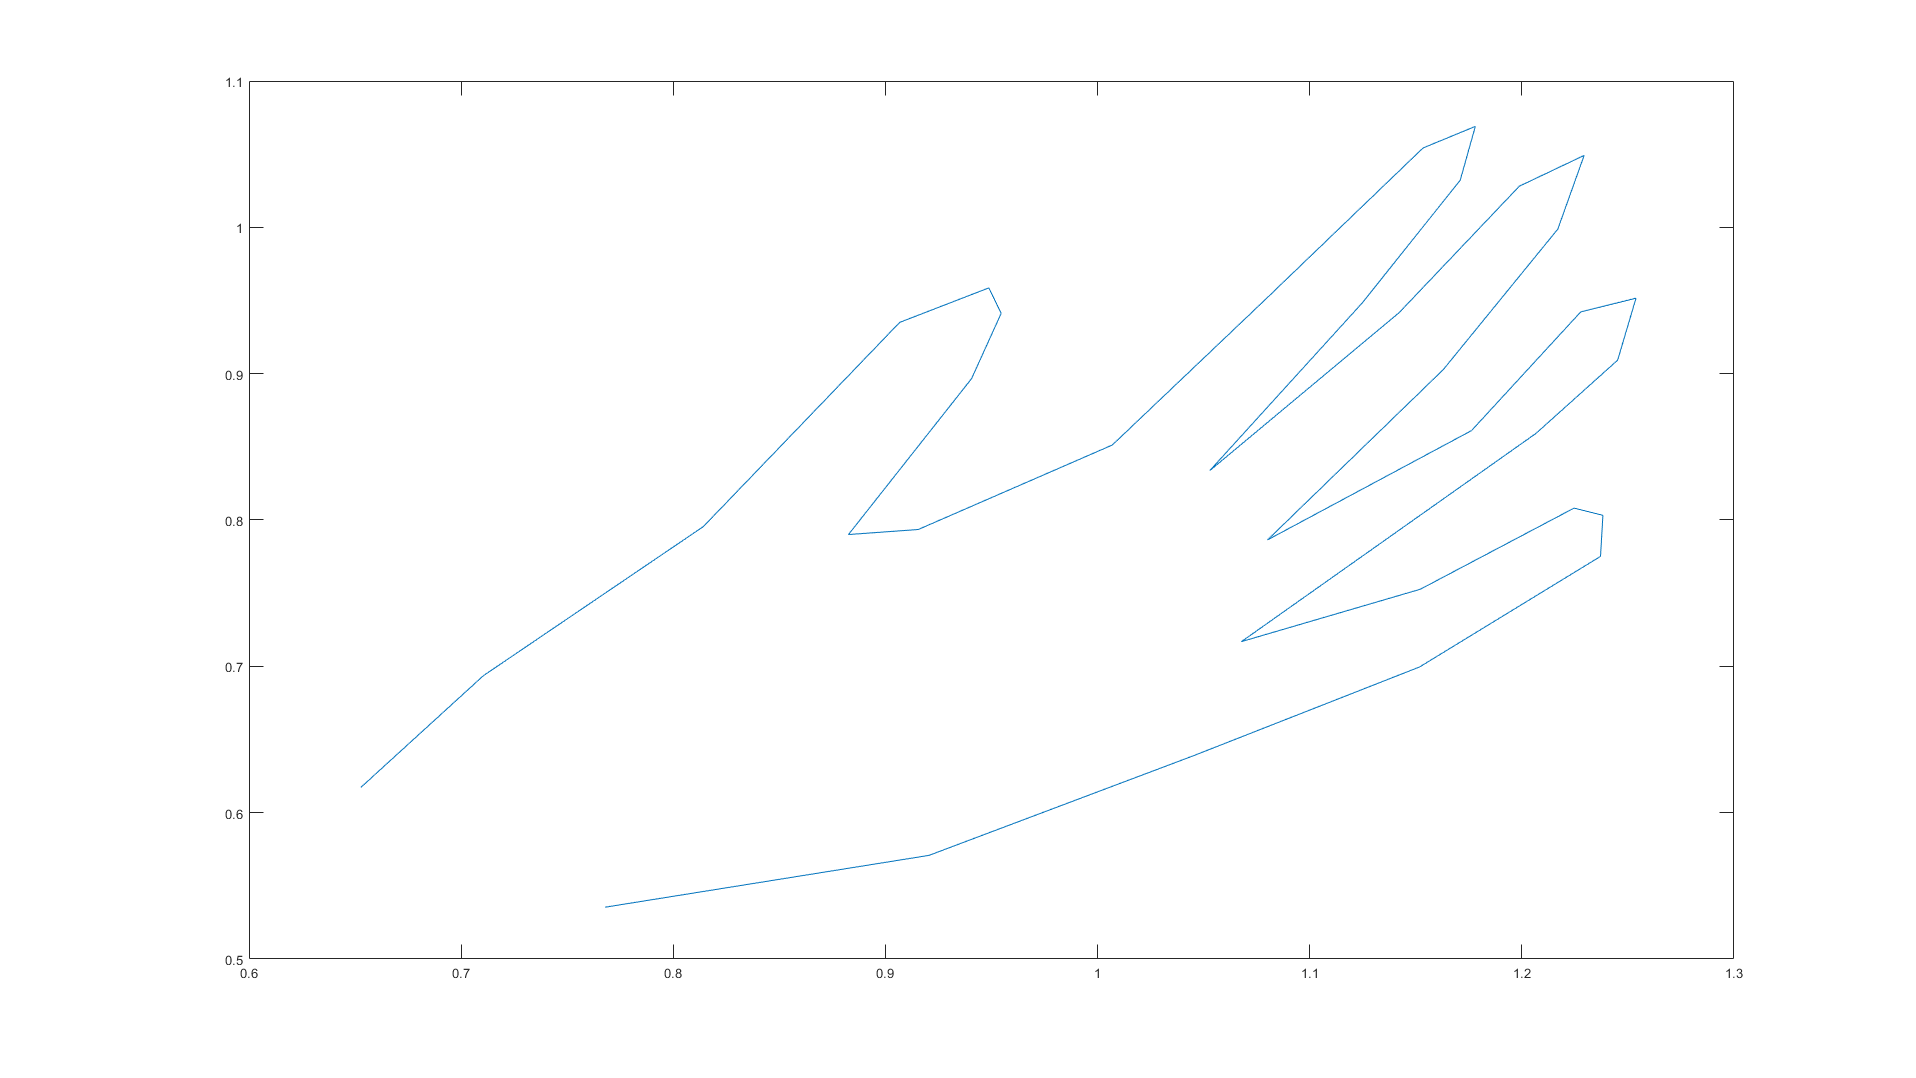

plot(theta,r);

delta = .05;
t = (theta(1):delta:theta(end))';
p = pchiptx(theta,r,t);
s = splinetx(theta,r,t)


s =

  0×1 empty double column vector



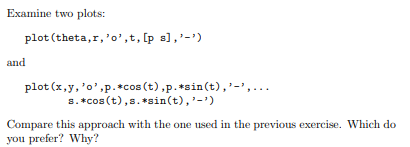

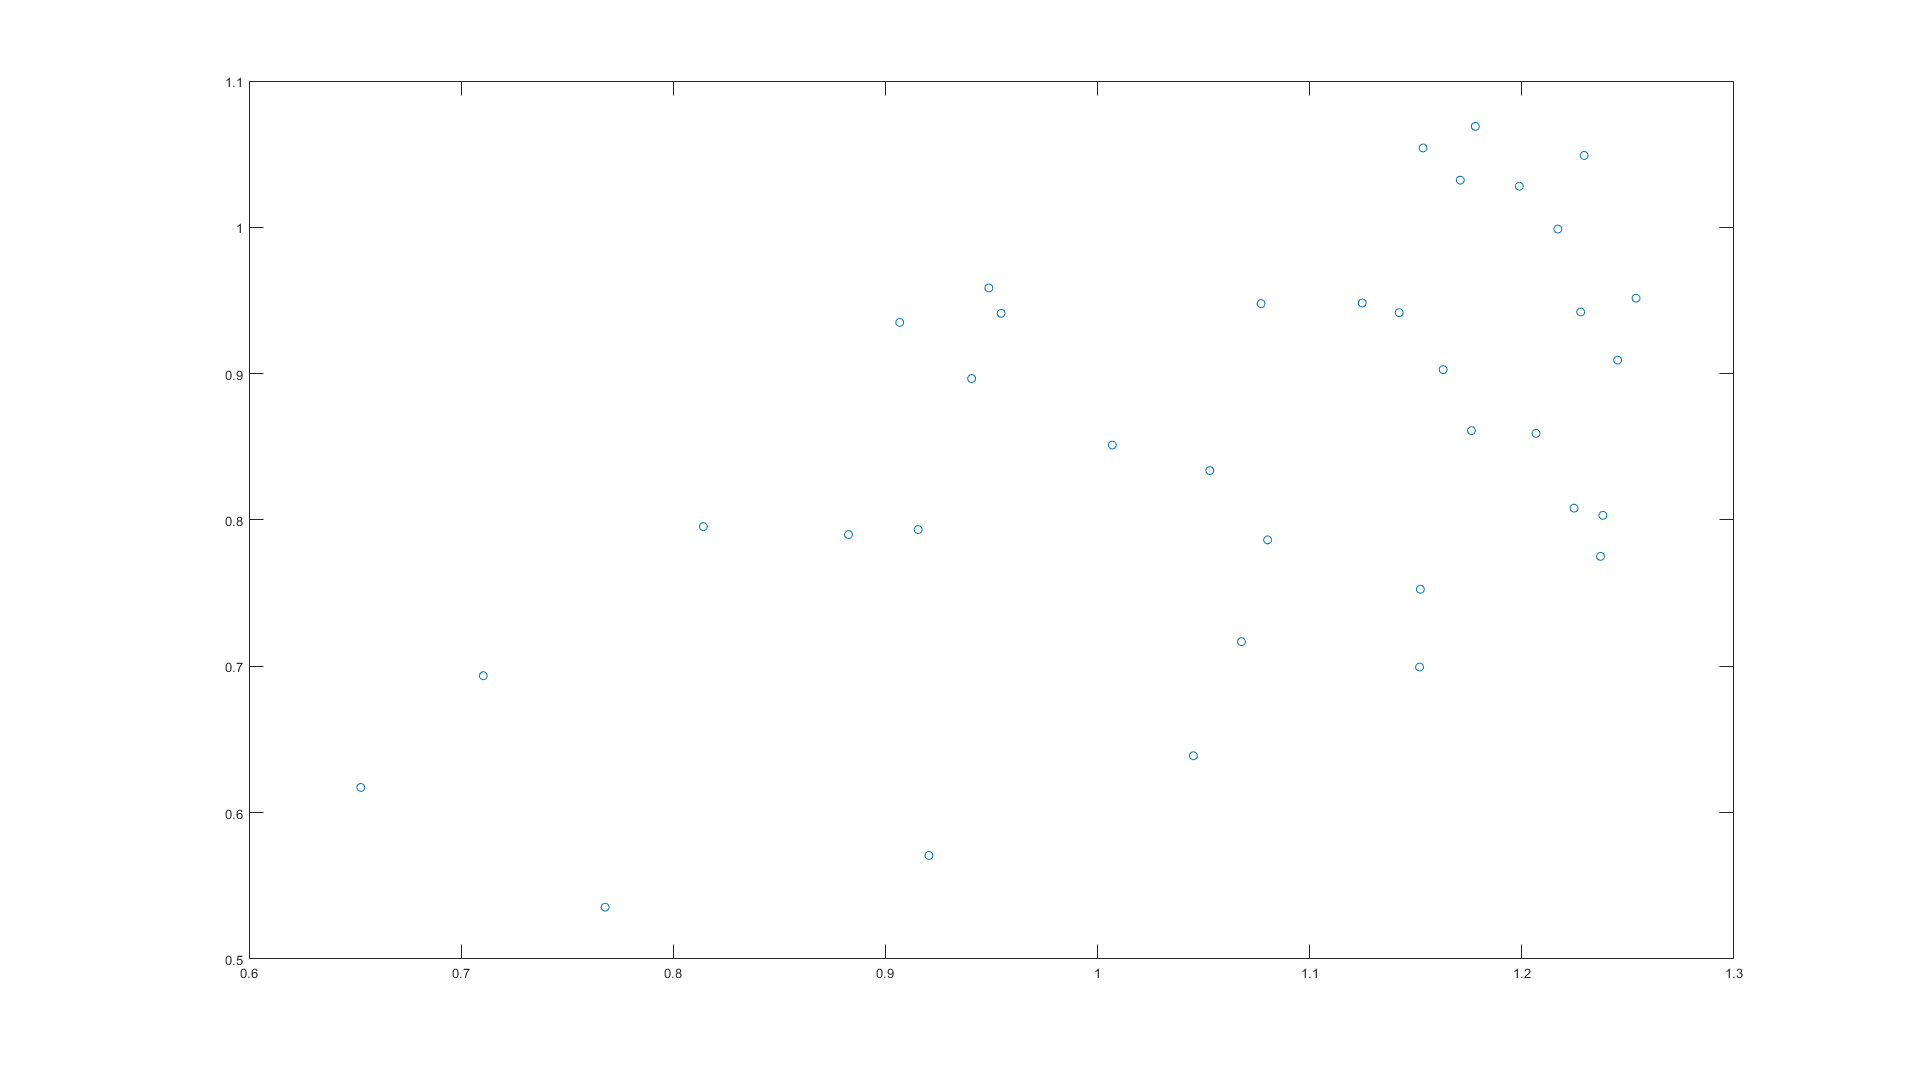

plot(theta,r,'o',t,[p s],'-')

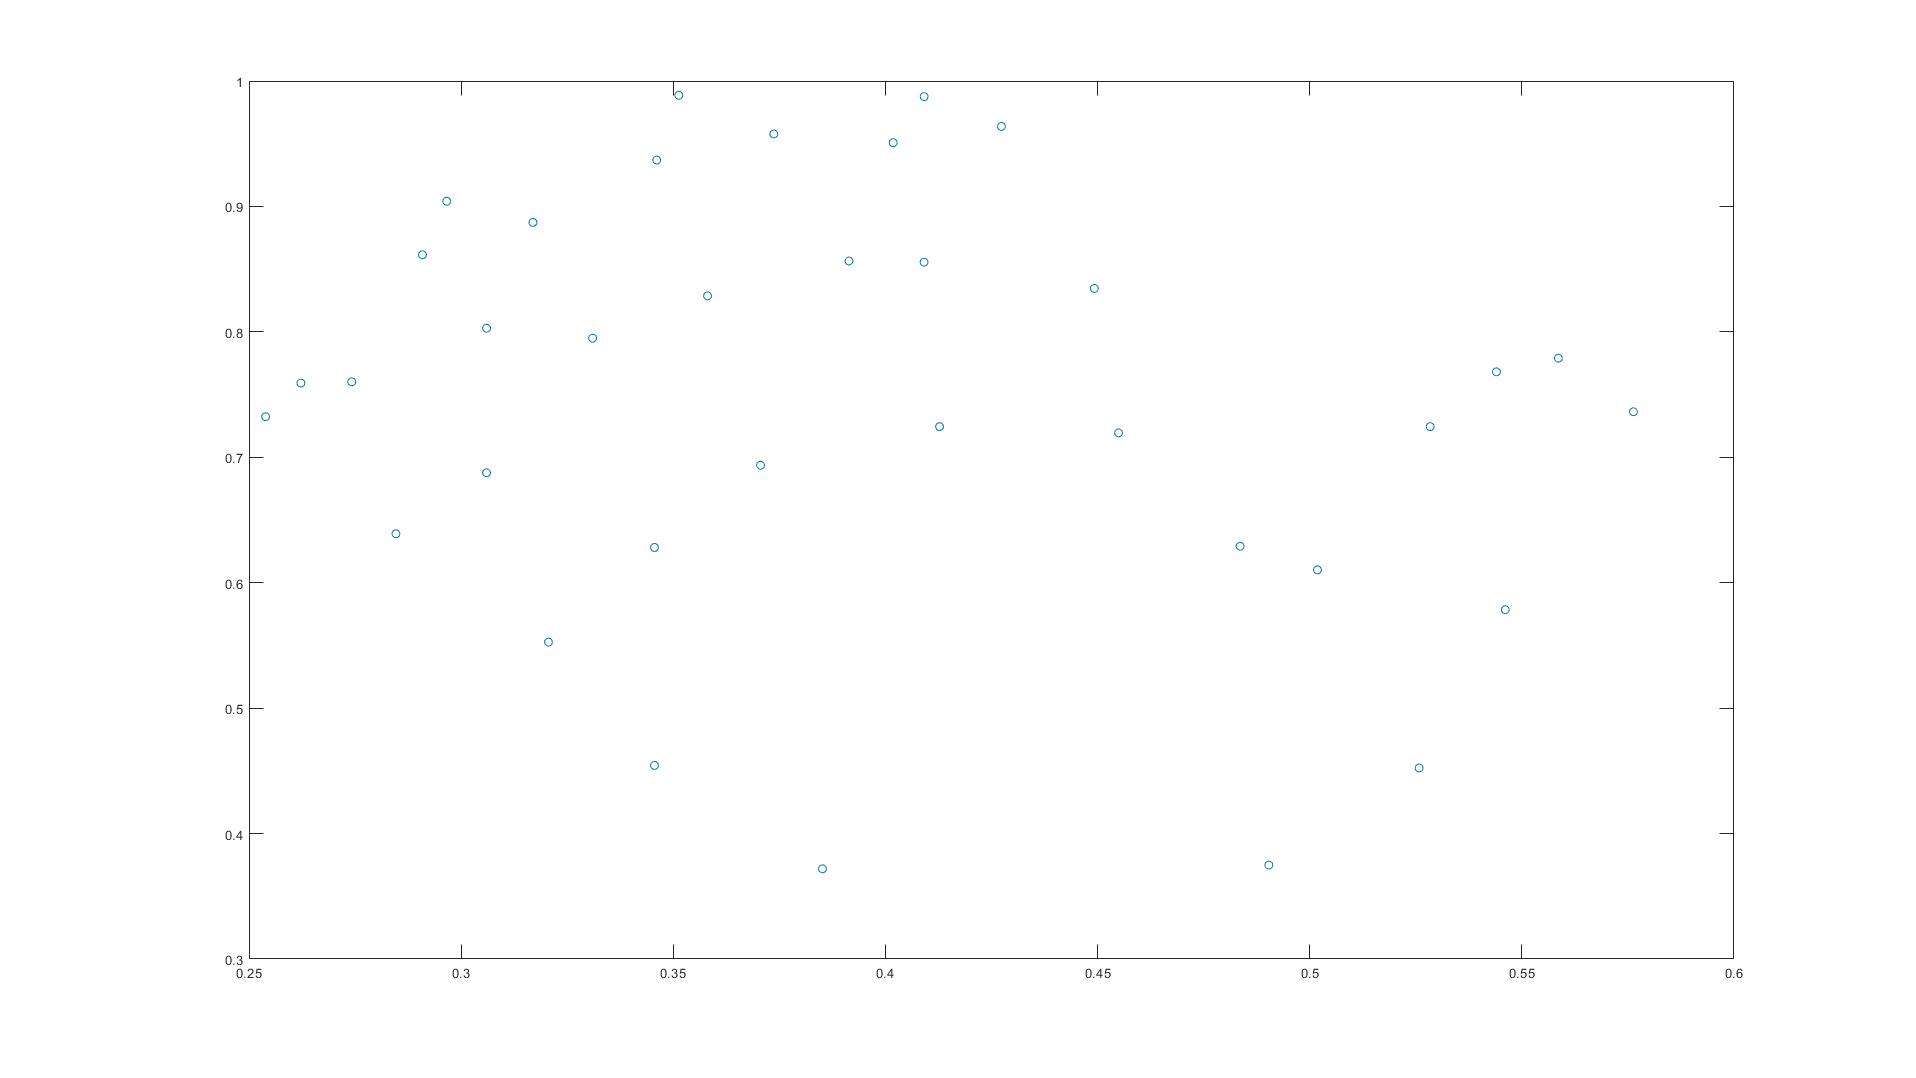

plot(x,y,'o',p.*cos(t),p.*sin(t),'-',...
s.*cos(t),s.*sin(t),'-')

**Exercici 1.2**

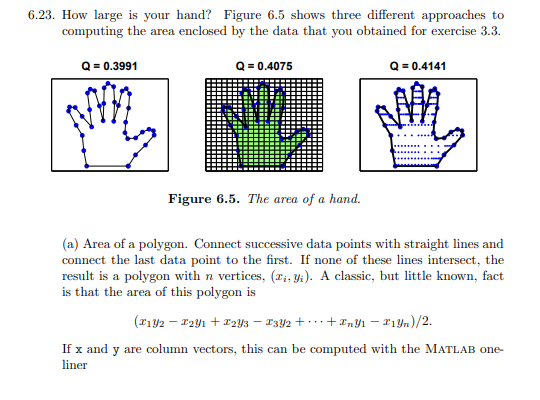

area = (x'*y([2:n 1]) - x([2:n 1])'*y)/2

area = -0.0962

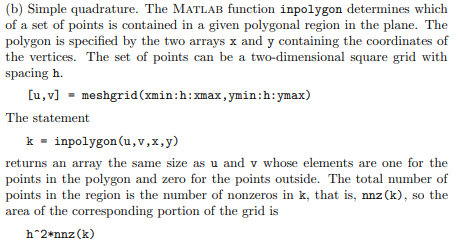

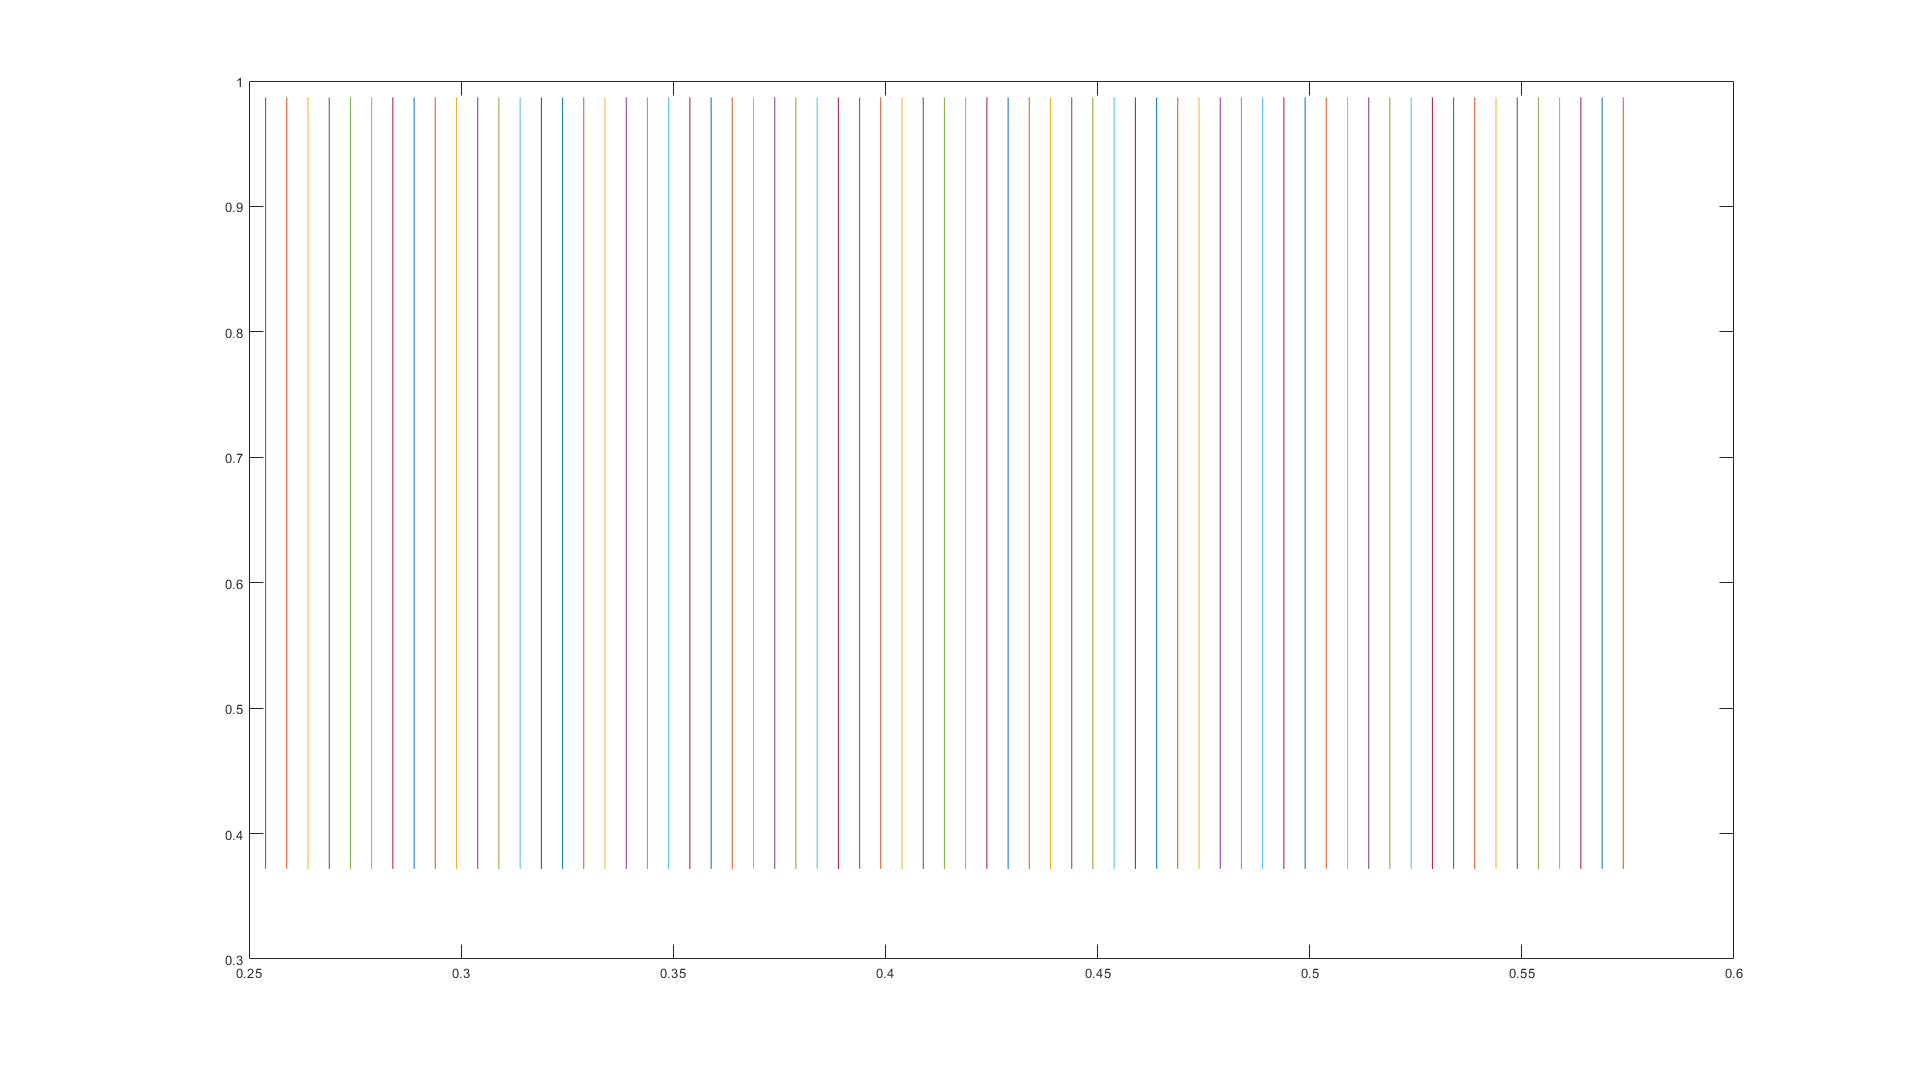

h = 0.005;
xmin = min(x);
xmax = max(x);
ymin = min(y);
ymax = max(y);
[u, v] = meshgrid(xmin:h:xmax,ymin:h:ymax);
k = inpolygon(u,v,x,y);
plot(u,v);

nnz(k);
radi = (h^2)*nnz(k)

radi = 0.0962

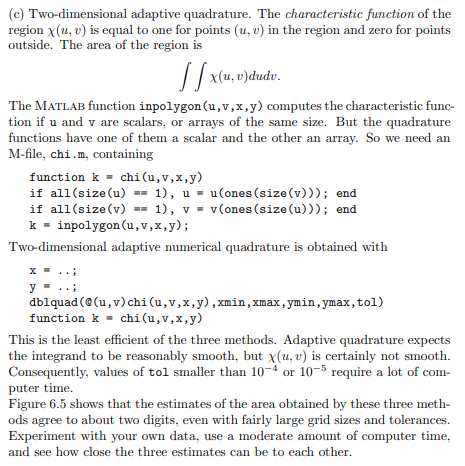

tol = 10^(-4);
radi = dblquad(@(u,v)chi(u,v,x,y),xmin,xmax,ymin,ymax,tol)

radi = 0.0972

# Exercici 2

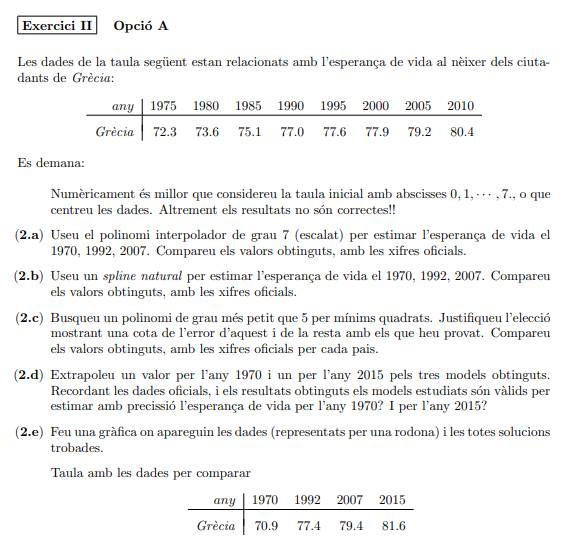

**2.a**

clear
clear output
x = [1975 1980 1985 1990 1995 2000 2005 2010];
y = [72.3 73.6 75.1 77.0 77.6 77.9 79.2 80.4];
grau = 7;
polyfit(x,y,grau)

ans = 	1.0e+15 *

    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0036   -1.0321


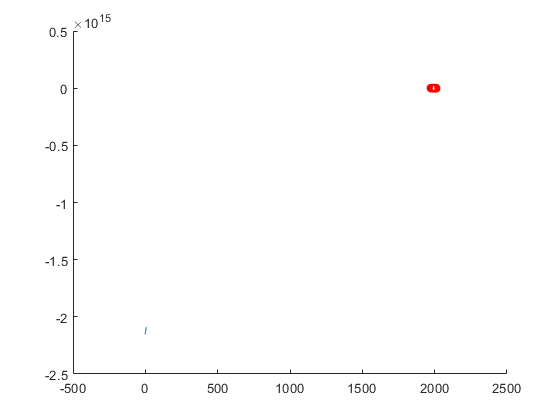

[p, ~, mu] = polyfit(x,y,grau);
scatter(x,y,'r');
hold on
xplot = -2:0.05:7;
yplot = polyval(p,xplot,[],mu);
plot(xplot,yplot);

solucio = polyval(p,-1,[], mu);
